# Pulse detector test bench (step 2)

© 2019-2020 The MathWorks, Inc.

This test bench creates a reference pulse detection algorithm, simulates the Simulink model implementation, and compares the Simulink result to the MATLAB reference.

## Create reference algorithm & parameters

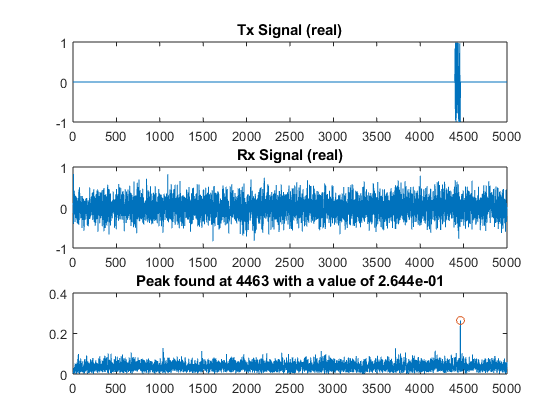

pulse_detector_reference;

## Simulate model and compare results to reference

if iscolumn(CorrFilter)
    CorrFilter = transpose(CorrFilter); % need row vector for filter block
end
SimTime = length(RxSignal) + WindowLen + 30;

% Simulate model
slout = sim('pulse_detector_v2_2');

% Correlation filter output
FilterOutSL = getLogged(slout,'filter_out');
FilterValid = getLogged(slout,'filter_valid');
FilterOutSL = FilterOutSL(FilterValid);
compareData(real(FilterOut),real(FilterOutSL),{2 3 1},'ML vs SL correlator output (re)');


Maximum error for ML vs SL correlator output (re) out of 5000 values
 6.938894e-17 (absolute), 2.665185e-14 (percentage)


compareData(imag(FilterOut),imag(FilterOutSL),{2 3 2},'ML vs SL correlator output (im)');


Maximum error for ML vs SL correlator output (im) out of 5000 values
 8.326673e-17 (absolute), 8.047260e-14 (percentage)


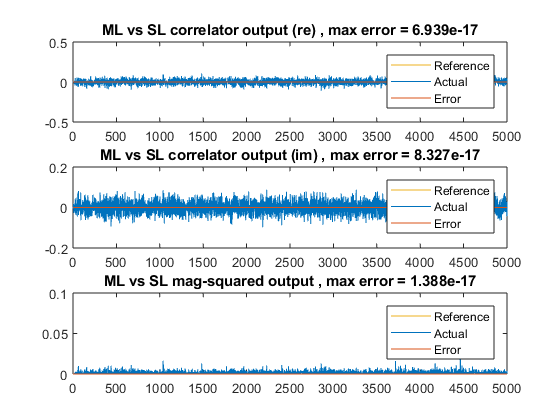


Maximum error for ML vs SL mag-squared output out of 5000 values
 1.387779e-17 (absolute), 1.985157e-14 (percentage)



% Magnitude squared output
MagSqSL = getLogged(slout,'mag_sq_out');
MagSqSL = MagSqSL(FilterValid);
compareData(MagSqOut,MagSqSL,{2 3 3},'ML vs SL mag-squared output');


% Peak value
MidSampleSL = getLogged(slout,'mid_sample');
Detected = getLogged(slout,'detected');
PeakSL = MidSampleSL(Detected>0);

fprintf('\nPeak location = %d, magnitude = %.3d using global max\n',location,peak);


Peak location = 4463, magnitude = 2.644e-01 using global max


fprintf('Peak location = %d, mag-squared = %.3d using local max\n',location_2,peak_2);

Peak location = 4463, mag-squared = 6.991e-02 using local max


fprintf('Peak mag-squared from Simulink = %.3d, error = %.3d\n',PeakSL,abs(peak_2-PeakSL));

Peak mag-squared from Simulink = 6.991e-02, error = 1.388e-17
